%% 纯ALOHA仿真
clc
clear
% 设置系统参数
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
N = 50;%用户数
lambdas = [linspace(0.000010,20,N/2) linspace(20,80,N/2)];%单个用户的帧到达率集合（是一个复数）
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
b = 100;
R = 1e5;
T_fr = b/R;
T = 1e2;%总仿真随机接入时长，可以根据仿真情况适当修改

lambdalength = length(lambdas);
rho_simu1 = zeros(size(lambdas));
rho_simu2 = zeros(size(lambdas));%设置某一用户在发送帧的过程中不会有新的帧到达该用户时计算的归一化吞吐速率
tic
for lambdaCounter = 1:lambdalength %对每个用户
    lambda = lambdas(lambdaCounter);%每个用户的lambda有各自的值
    MAX_number_of_arrived_frames_in_T_for_each_user=ceil(T*lambda + 5*sqrt(T*lambda));%在仿真时间内可以有的最大arrival帧数
    % 生成所有用户的帧到达时刻(帧到达即发送)-TotalFrameArrivalTimes
    TotalFrameArrivalTimes1 = [];
    TotalFrameArrivalTimes2 = [];
    for n = 1:N
        %%%%%对"1"
        FrameArrivalTimes=zeros(1,MAX_number_of_arrived_frames_in_T_for_each_user);%记录帧到达时间的数组
        number_of_arrived_frames=0;%初始化：刚开始时没有帧到来
        FrameArrivalTime = -1/lambda*log(rand);%初始化：第一帧到来时间；后面记录总的到来时刻
        while FrameArrivalTime<T
            number_of_arrived_frames=number_of_arrived_frames+1;
            FrameArrivalTimes(number_of_arrived_frames) = FrameArrivalTime;
            FrameArrivalTime=FrameArrivalTime+(-1/lambda)*log(rand);%每次按照随机的时间来增加
        end%不断往复的记录，直到超出仿真时间
        TotalFrameArrivalTimes1 = [TotalFrameArrivalTimes1 FrameArrivalTimes];%每个用户的arrival时间并入总信道的arrival时间
        
        %%%%%对"2"，一样的操作
        FrameArrivalTimes=zeros(1,MAX_number_of_arrived_frames_in_T_for_each_user);
        number_of_arrived_frames=0;
        FrameArrivalTime = -1/lambda*log(rand);
        while FrameArrivalTime<T
            number_of_arrived_frames=number_of_arrived_frames+1;
            FrameArrivalTimes(number_of_arrived_frames) = FrameArrivalTime;
            FrameArrivalTime=FrameArrivalTime+T_fr+(-1/lambda)*log(rand);%这里有不同之处，是设置2的属性
        end
        TotalFrameArrivalTimes2 = [TotalFrameArrivalTimes2 FrameArrivalTimes];
    end

    % 统计仿真时长T内总的成功发送的帧的数量并计算归一化吞吐速率 
    rho_simu1(lambdaCounter) = TotalSuccessFrameNumCalcu(TotalFrameArrivalTimes1,T_fr)/T*T_fr;%num*Tfr是成功传输所使用的时长
    rho_simu2(lambdaCounter) = TotalSuccessFrameNumCalcu(TotalFrameArrivalTimes2,T_fr)/T*T_fr;
end
toc

历时 1.637180 秒。


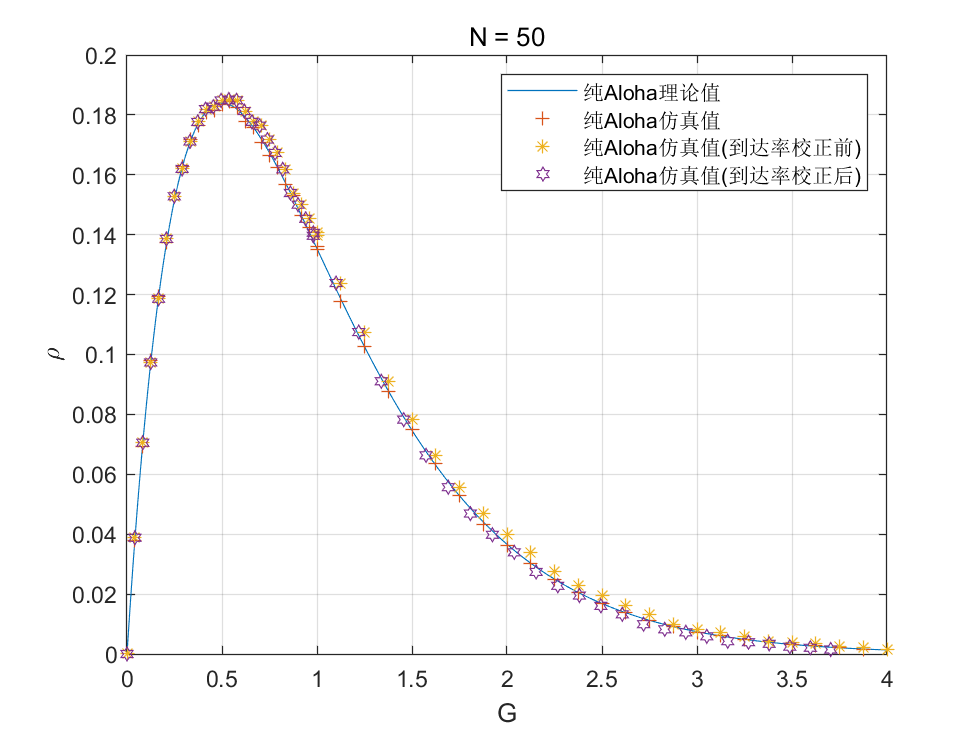



%画图部分代码
figure
G_s = 0:0.01:N*lambdas(end)*T_fr;
plot(G_s,G_s.*exp(-2*G_s),'DisplayName','纯Aloha理论值')%理论公式直接绘图
hold on
plot(N*lambdas*T_fr,rho_simu1,'+','DisplayName','纯Aloha仿真值')
hold on
plot(N*lambdas*T_fr,rho_simu2,'*','DisplayName','纯Aloha仿真值(到达率校正前)')
hold on
plot(N*(lambdas./(1+lambdas*T_fr))*T_fr,rho_simu2,'hexagram','DisplayName','纯Aloha仿真值(到达率校正后)')
legend
grid on
title(['N = ', num2str(N)])
xlabel('G')
ylabel('\rho')

function TotalSuccessFrameNum = TotalSuccessFrameNumCalcu(TotalFrameArrivalTimes,T_fr)
%统计成功帧数的函数
%原理就是根据"脆弱时间"的定义判定前面随机生成的所有用户产生的Frame发送时间"TotalFrameArrivalTimes"中有多少成功传递了
    TotalSuccessFrameNum = 0;
    TotalFrameArrivalNum = length(TotalFrameArrivalTimes);
    TotalFrameArrivalTimes_sorted = sort(TotalFrameArrivalTimes);%升序排列
    %下面三if语句都是确保不在脆弱时间内有其他arrival，确保是Success的Frame
    if TotalFrameArrivalTimes_sorted(2) > TotalFrameArrivalTimes_sorted(1)+T_fr
        TotalSuccessFrameNum = TotalSuccessFrameNum+1;
    end
    for i = 2 : TotalFrameArrivalNum-1
        if (TotalFrameArrivalTimes_sorted(i)>TotalFrameArrivalTimes_sorted(i-1)+T_fr) && ...
                (TotalFrameArrivalTimes_sorted(i)<TotalFrameArrivalTimes_sorted(i+1)-T_fr)
            TotalSuccessFrameNum = TotalSuccessFrameNum+1;
        end
    end    
    if TotalFrameArrivalTimes_sorted(TotalFrameArrivalNum) > TotalFrameArrivalTimes_sorted(TotalFrameArrivalNum-1)+T_fr
        TotalSuccessFrameNum = TotalSuccessFrameNum+1;
    end
end